First create a simulator object.

s = radon.Simulator;

Finder constructor v3.00
Simulator constructor v1.04


Lets give the simulator the line start and end coordinates:

s.x1 = 0.375; s.x2 = 0.5; s.y1 = 0; s.y2 = 0.5;
s.run()

running streak detection on b=    | f=     | s= ...  | length= 1054 | bestSNR= 40.363533
saving streaks with SNR= 40.3635


The finder inside "s" has managed to locate the streak. Lets show it on screen.

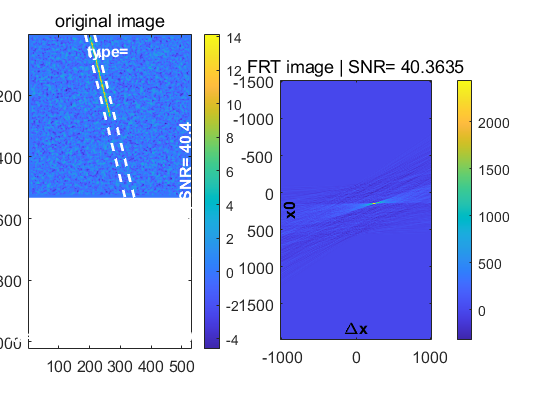

s.finder.streak.show('LineOffset', 15, 'FontSize', 12);

It looks like the streak is found in the correct position.

Now lets see how to use the finder on an image. 

First generate a streak using the Simulator:

s.x1 = 0.2; s.x2 = 0.6; s.y1 = 0; s.y2 = 0.5; s.run();

running streak detection on b=    | f=     | s= ...  | length= 1310 | bestSNR= 48.833372
saving streaks with SNR= 48.8334


noiseless_line_image = s.image_conv;
clf;
util.plot.show(noiseless_line_image);

Add this line to a single image inside a batch of ten "noise only" images 

(with realistic noise properties for the Andor Zyla 5.5 we are using)

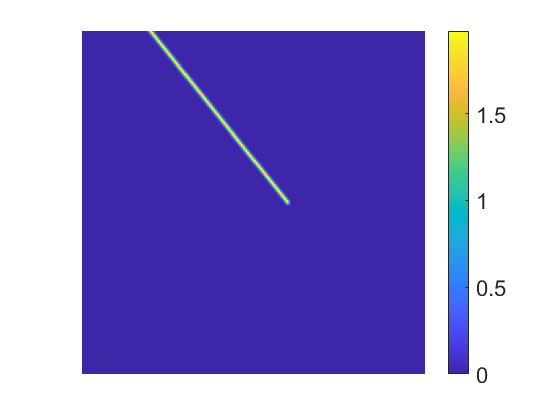

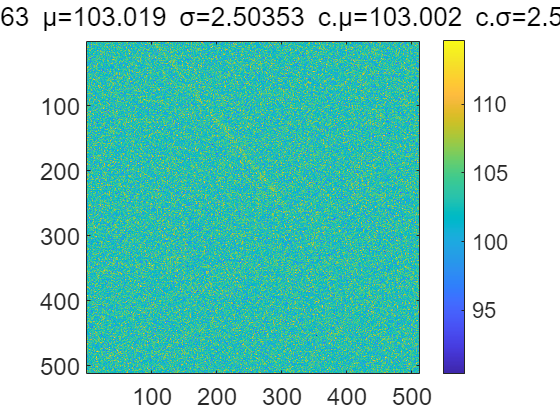

I = normrnd(ones(512,512,10)*103,2.5);
I(:,:,3) = I(:,:,3) + noiseless_line_image;
util.plot.show(I(:,:,3));

Now input the images to the finder:

f = radon.Finder;

Finder constructor v3.00


f.use_exclude = 0;
f.use_subtract_mean = 1;
f.use_short = 1;
f.reset;
f.input(I(:,:,3), 'psf', 2, 'var', 2.5^2);

running streak detection on b=    | f=     | s= ...  | length= 327 | bestSNR= 24.188033
saving streaks with SNR= 24.188


Note how the 9 empty frames have S/N below 5, while the streak is detected at S/N~23

We can use the simulator to estimate the S/N 

s.bg_noise_var = 2.5^2;
s.calcSNR

ans = 27.2003

Additional inputs to the Finder.input() method include:

-filename, batch_num: To keep track of where each streak was found

-psf: as a scalar (PSF width  σσ ) or a 2D map

-variance: a scalar (average background variance) or a 2D map

Some of the properties of Finder that can be used to improve streak detection:

-use_subtract_mean=1: each image mean is subtracted, ignoring NaNs (NaNs are then replaced with zeros).

-use_conv=1: choose if to convolve the image before doing FRT.

-use_crop=0: reduce the image size (never enlarge). Good for clipping images not in powers of 2.

-crop_size=2048: what size to crop to. Use a power of 2 as close as possible to image size. Crops the middle of the image.

-use_short=1: find short streaks.

-min_length=32: shortest streaks to save (pixels along the horizontal/vertical)

-threshold=10: in units of S/N.

-use_recursive=0: apply FRT again and again, subtracting the streaks each time.

-recursive_depth=10: how many times (per transposition!).

-use_only_one=1: when not recursive, save only one streak from the two transpositions.

-subtract_psf_widths=3: how many PSF σσ's to subtract in each direction of the streak.

-use_exclde=1: Zeros the central part of the Radon image before finding maxima (gets rif of line-noise).

-exclude_dx=[-50,50]: horizontal pixel range (in final Radon image; for partial frames uses a relative size).

-exclude_dy=[]: same as above, for the vertical pixel range.

-use_save_images=1: saves a copy of the original and Radon image (and subframe). Use 0 to save space.

You can also use the FRT directly on any image:

(make sure to use transpose is the streak is above 45 degrees)

R = radon.frt(I(:,:,3)-util.stat.mean2(I(:,:,3)), 'trans', 1);
util.plot.show(R);

This is good enough to find it, but it isn't normalized to S/N units. 

For that we need the Radon variance map:

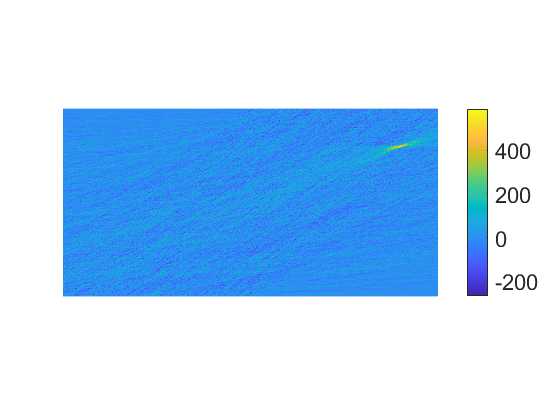

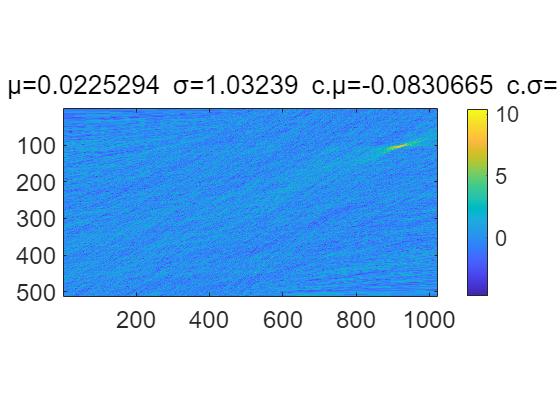

VR = radon.frt(ones(512,512)*2.5^2, 'trans', 1);
util.plot.show(R./sqrt(VR));

If we want to do short streak detection we should use the Finder. 

We can give it to the FRT function as an optional argument:

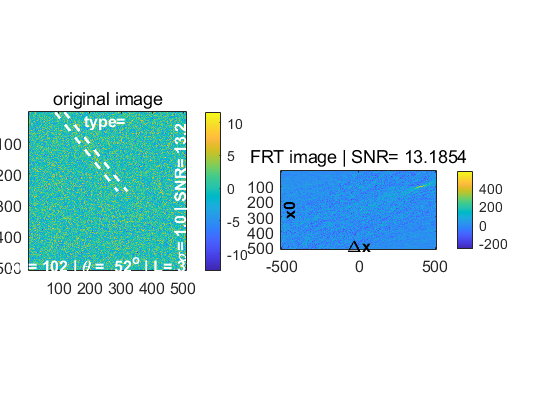

f.reset;
R = radon.frt(I(:,:,3)-util.stat.mean2(I(:,:,3)), 'trans', 1, 'finder', f);
f.streak.show('LineOffset', 15, 'FontSize', 12);